# Visualize acoustic tunnel simulated data

#### Load all the data

%load array geometry
load("Sub Functions and Data\AcousticTunnelBasicGeometry.mat")

#### Visualize the input signal and the signal at some microphones

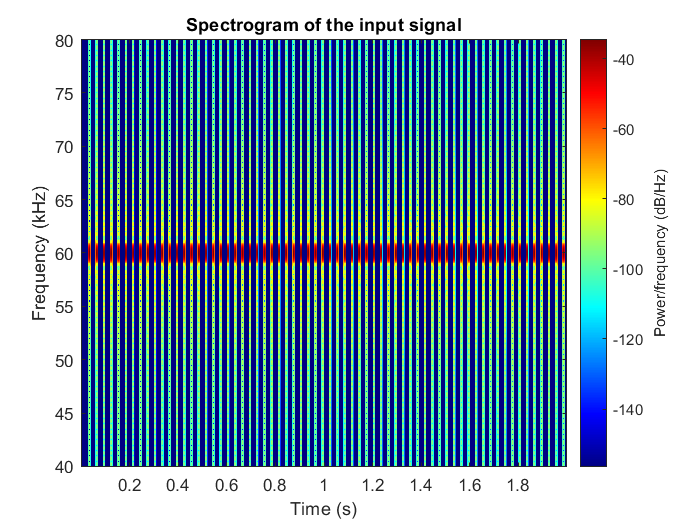

%get the sampling frequency
Fs = fullInputStruct.Fs;

%show the input signal
figure(1)
clf
spectrogram(fullInputStruct.signal,1000,500,40*1e3:100:80*1e3,Fs,'yaxis');
title("Spectrogram of the input signal")
colormap('jet')

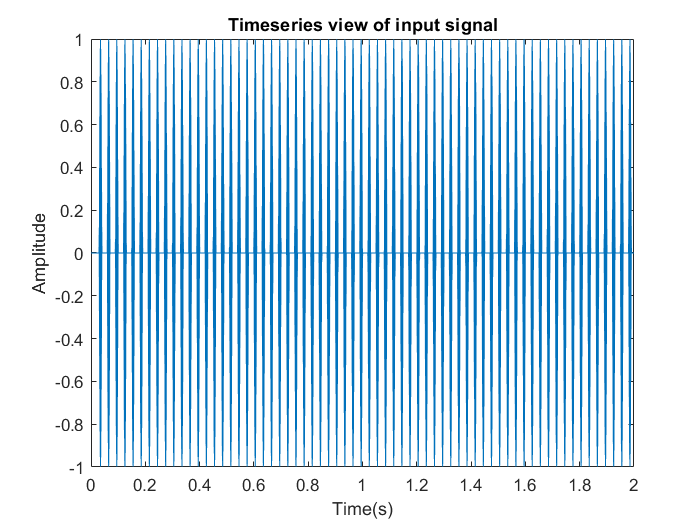


%plot the timeseries of the input signal
figure(2)
clf
plot(fullInputStruct.timeSteps,fullInputStruct.signal);
xlabel("Time(s)")
ylabel("Amplitude")
title("Timeseries view of input signal")

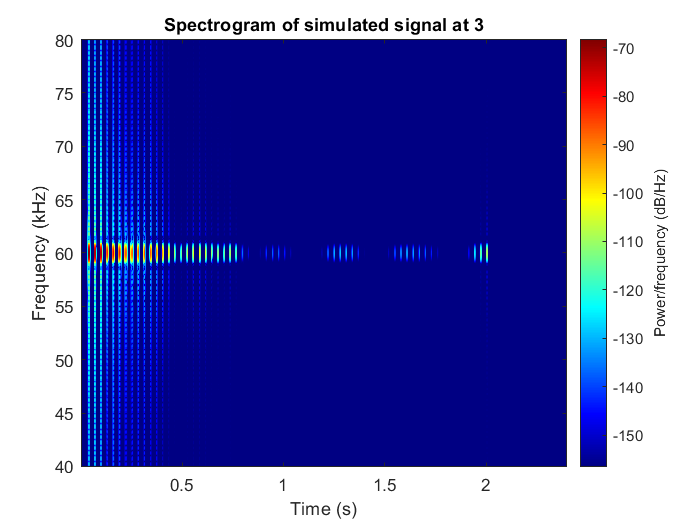


%get the microphone number to plot
micNum = 3;

%the geometry number to plot
geomNum = 1;

%plot the output at the microphone
figure(3)
clf
spectrogram(fullSolutionStruct(geomNum).geomSolutions(micNum,:),1000,500,40*1e3:100:80*1e3,Fs,'yaxis');
title("Spectrogram of simulated signal at " + string(micNum))
colormap('jet')

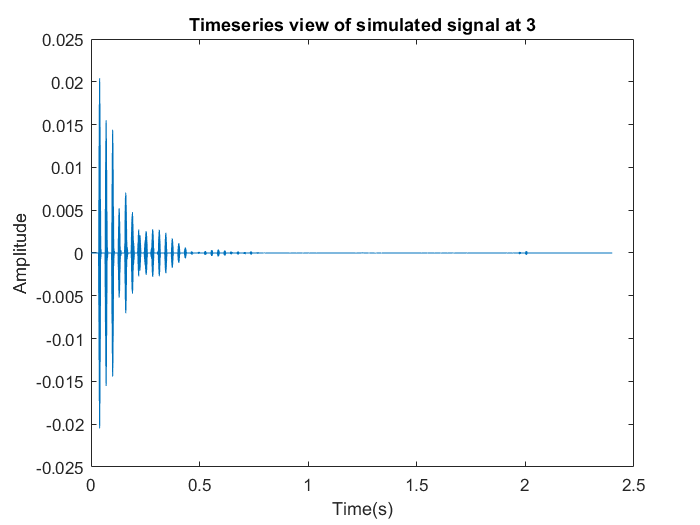


%plot the timeseries of the input signal

%get the solution timesteps
soltSteps = 1:1:length(fullSolutionStruct(geomNum).geomSolutions(micNum,:));
soltSteps = soltSteps*(1/Fs);

figure(4)
clf
plot(soltSteps,fullSolutionStruct(geomNum).geomSolutions(micNum,:));
xlabel("Time(s)")
ylabel("Amplitude")
title("Timeseries view of simulated signal at " + string(micNum))